clc
clear all
close all


data = csvread("ntc.csv");

ad = data(:,2);
t = data(:,1);

adc= 1023.*(ad./(ad+10));

figure(1)
xlabel('ADC value');
ylabel('Temperature°C')
plot(adc,t, 'o')
hold on

p = polyfit(adc, t, 10); 

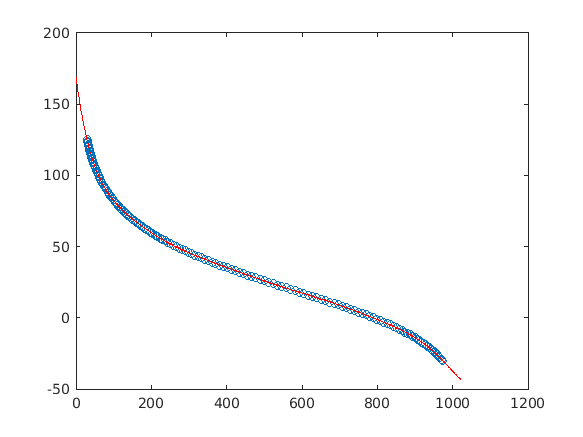

ad2 = 0:1023;
t2 = round(polyval(p, ad2), 1);
plot(ad2, t2, 'r');

dlmwrite('data.dlm', t2*10, ','); 



 
